Exercici 2

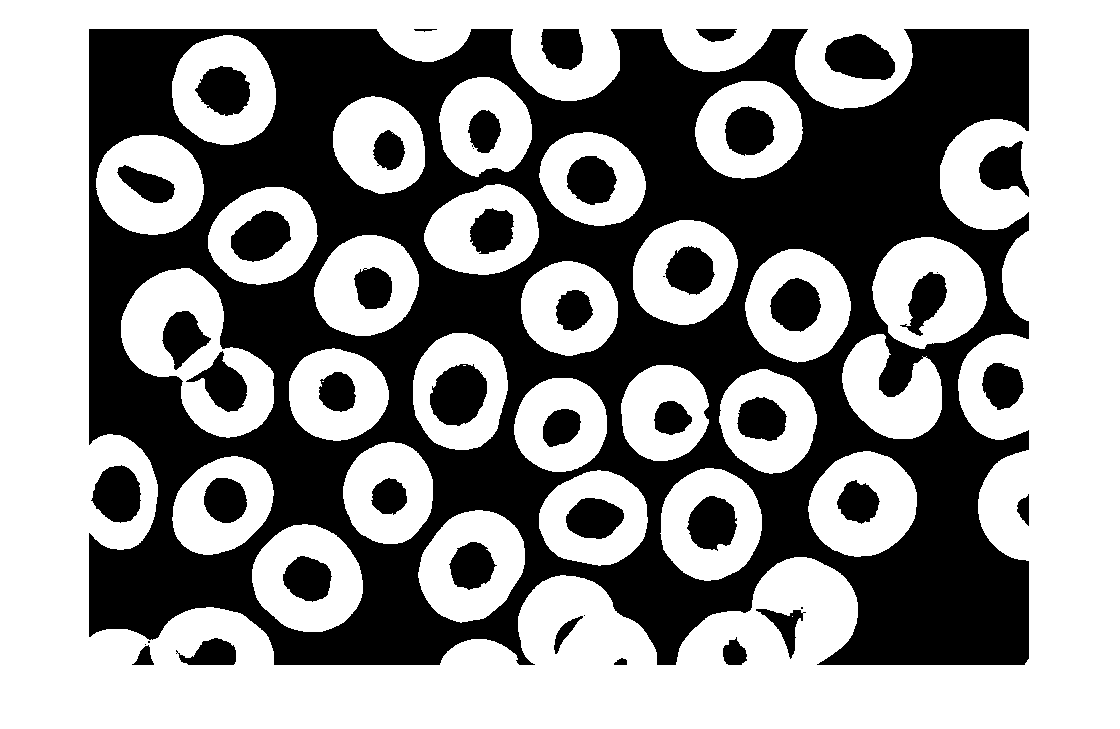

I= imread("normal-blood1.jpg");

% PASSEM A BLANC I NEGRE PER A PODER BINARITZAR

BW= rgb2gray(I);

% MIRANT EL VALOR APROXIMAT DE UNA CEL·LULA LES BINARITZEM

cell= BW < 190;
imshow(cell);

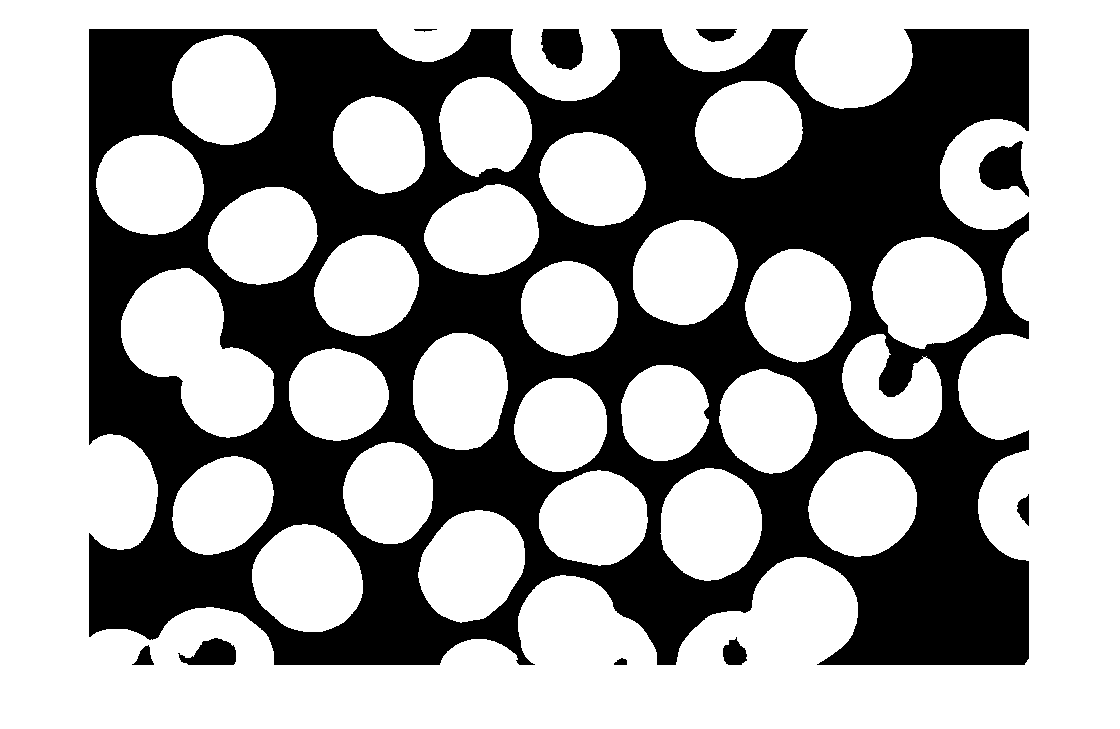

% UTILITZANT FILL INTENTEM OMPLIR ELS BUITS DE LES CEL·LULES

Fill = imfill(cell, 'holes');
imshow(Fill);

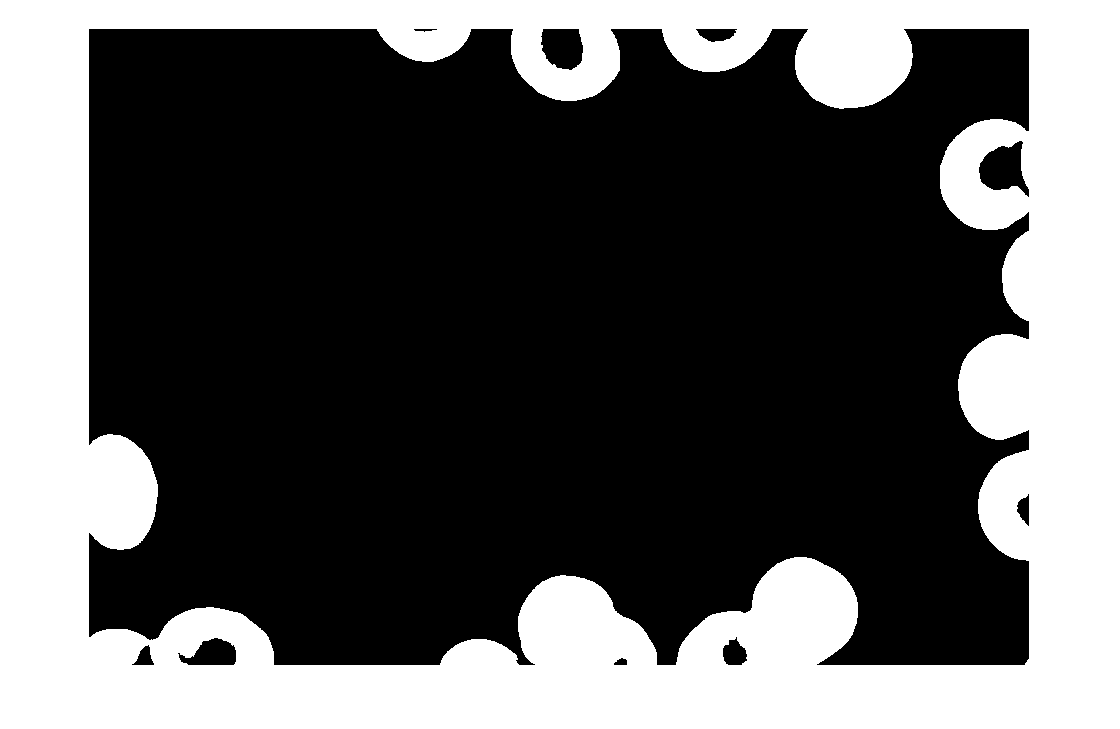

% ENS PREPAREM PARA A ELIMINAR LES QUE ES TROBEN A LA VORA

bw = zeros(size(cell));
bw(:,1) = 1;
bw(1,:)=1;
bw(size(cell,1),:)=1;
bw(:,size(cell,2))=1;
bw = (bw == 1);

% AMB UNA RECONSTRUCCIÓ ACONSEGUIM LES CEL·LULES QUE VOLEM ELIMINAR
Rec= imreconstruct(bw,Fill);
imshow(Rec);

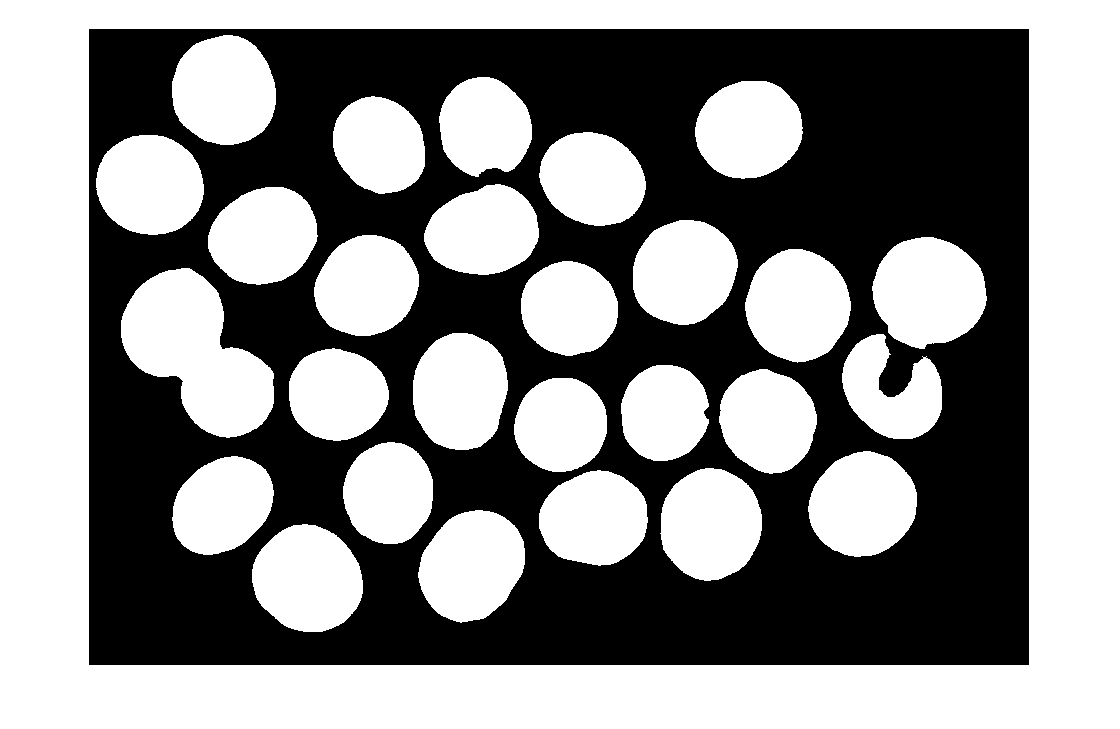

% AMB LA RESTA DE LES DUES IMATGES OBTENIM LES DEL CENTRE

Res= Fill-Rec;
imshow(res);

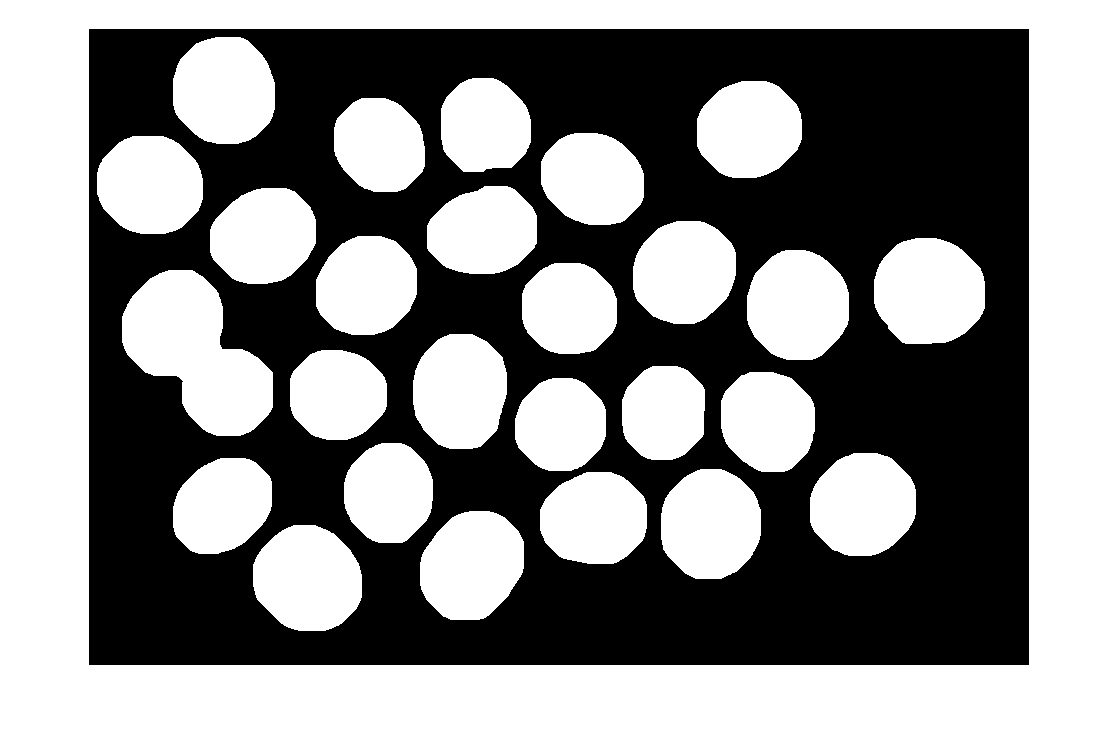

% REALITZEM UN OPEN PER A ELIMINAR LA CEL·LULA QUE NO HEM ACONSEGUIT TANCAR
% EL SEU CENTRE

SE = strel('disk', 25);
O=imopen(Res,SE);
imshow(O);

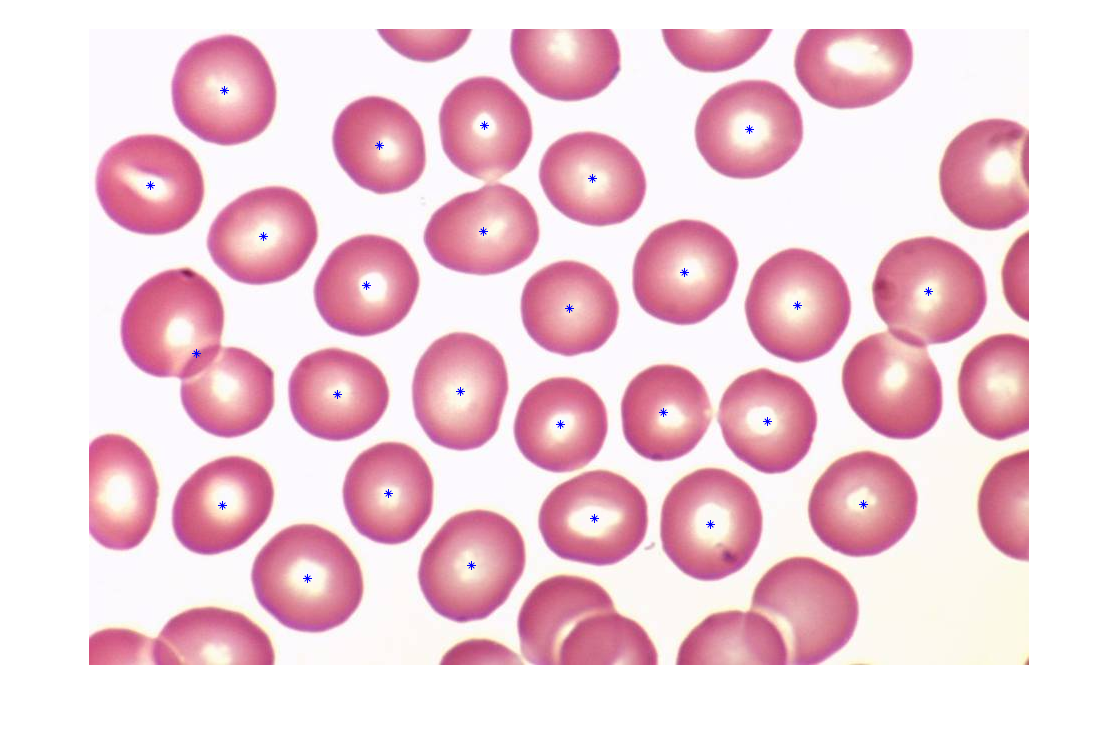

% OBTENIM EL NOMBRE DE COMPONENTS CONNEXES I OBTENIM ELS SEUS CENTRES I
% REALITZEM EL PLOT CONJUNT

Con = bwconncomp(O);

nPixels = cellfun(@numel, Con.PixelIdxList);
cells = nPixels < 20;
pos = find(cells);

S = regionprops(Con,'centroid');

figure;imshow(I);
hold on;
S(pos) = [];
Centroids = cat(1, S.Centroid);
plot(Centroids(:,1),Centroids(:,2),'b*');

Exercici 3

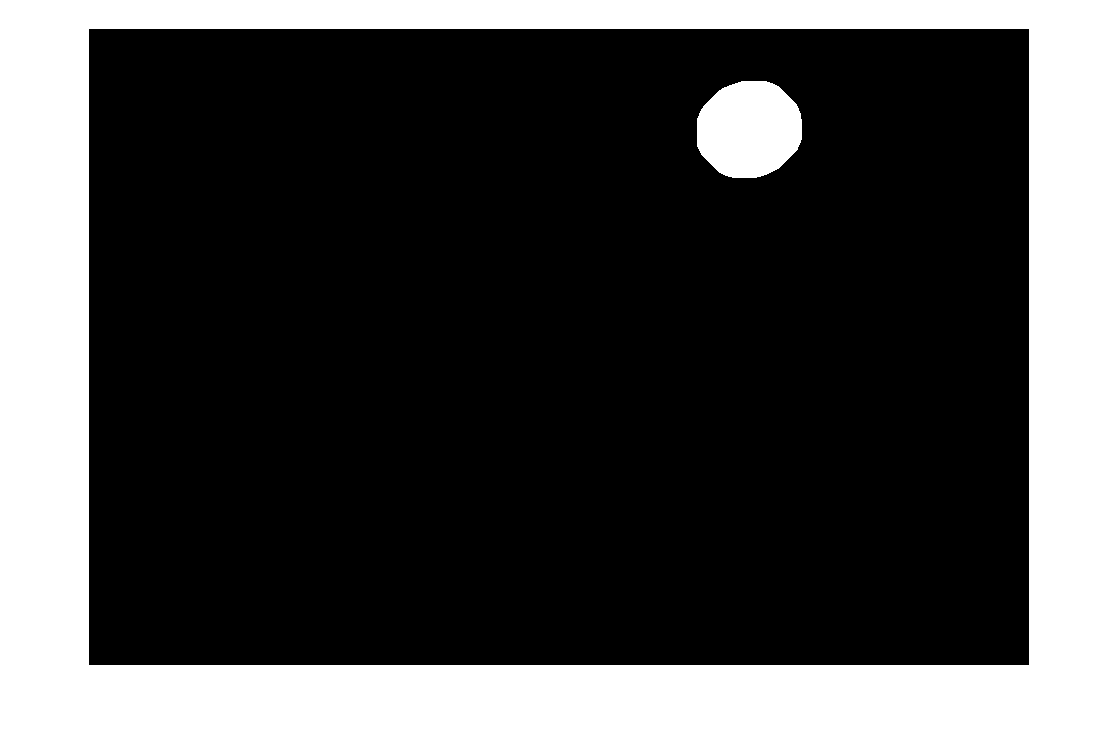

% CREEM UN ELEMENT ESTRUCTURANT D'UN PIXEL DE GRUIX PER A PODER ANAR
% DILATANT LA IMATGE FINS QUE NOMÉS TINGUEM DOS COMPONENTS CONNEXES
% LA QUE ESTIGUI MÉS LLUNY DE LES ALTRES

SE= strel('disk', 1);
D=O;
numCells= Con.NumObjects;
iterations=0;
while numCells > 2
    D=imdilate(D,SE);
    single= bwconncomp(D,4);
    numCells= single.NumObjects;
    iterations= iterations + 1;
end

% IDENTIFIQUEN EL BLOB AMB MENOR TAMANY

blobs = single.PixelIdxList;
min = inf;
for i = 1:size(blobs,2)
    AUX = cell2mat(blobs(1,i));
    aux = size(AUX,1);
    if aux < min
        min = aux;
        BLOB = AUX;
    end
end

% PROCEDIM A MARCAR EL BLOB CORRESPONENT I A RECUPERAR EL SEU TAMANY
% ORIGINAL REALITZANT TANTES EROSIONS COM DILATACIONS HEM REALITZAT PER A
% OBTENIRLA

rows= size(O,1);
cols= size(O,2);

R = zeros(rows,cols);
for k = 1:size(BLOB)
    i = uint32(mod(BLOB(k),rows));
    if i == 0
        i = rows;
    end
    j = uint32(BLOB(k)/rows) + 1;
    R(i,j) = 255;
end

for it= 1:iterations
    R=imerode(R,SE);
end
imshow(R);